# Second order active filter

Copyright (C) 2021 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

## Introduction 

% Exact linearization of the Simulink model filter_80hz
% Specify the model name
model = 'SallenKeyFilter';

Specify the analysis I/Os

Get the analysis I/Os from the model

io = getlinio(model);

Specify the operating point

Use the model initial condition

op = operpoint(model);

Linearize the model

sys = linearize(model,io,op);

Plot the resulting linearization

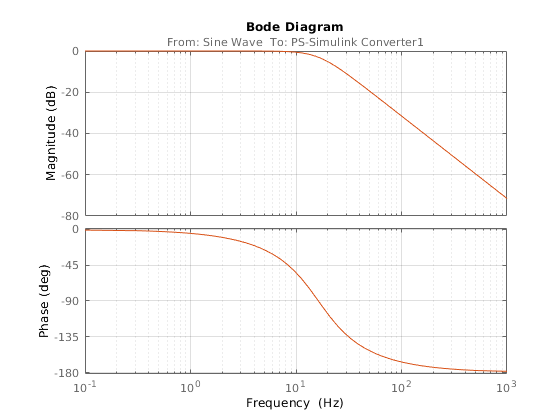

h = bodeplot(sys);
setoptions(h,'FreqUnits','Hz','PhaseVisible','on');
hold on
p = bodeoptions('cstprefs');
p.FreqUnits = 'Hz';
p.Grid = 'on';
p.Xlim{1}(1)=10^-1;
p.Xlim{1}(2)=10^3;
p.PhaseWrapping='on';
bodeplot(sys,p)